estConst = EstimatorConst();

pA = estConst.pA;
pB = estConst.pB;
d = estConst.d;
phi_0 = estConst.phi_0;
l = estConst.l;

N_particles = 10;
r = d * sqrt(rand(1,N_particles));
theta = rand(1,N_particles) * 2 * pi;

center_seed = rand()

center_seed = 0.4551

if center_seed<=0.5
    centerX = repmat(pA(1),1,N_particles) ;
    centerY = repmat(pA(2),1,N_particles) ;
else
    centerX = repmat(pB(1),1,N_particles);
    centerY = repmat(pB(2),1,N_particles);
end

xr = centerX + r .* cos(theta)

xr =     0.9448    0.9386    1.0651    1.1368    1.1658    1.0405    1.0439    0.9683    1.1561    1.2455


yr = centerY + r .* sin(theta)

yr =     0.7023    0.6177    0.6075    0.4886    0.7354    0.6003    0.6959    0.6761    0.5996    0.6585



phi_r = -phi_0 + 2*phi_0*rand(1,N_particles)

phi_r =     0.5670    0.7532    0.6150   -0.7437   -0.4629   -0.4137   -0.5084   -0.2581    0.1068   -0.5688


l_r = -l + 2*l*rand(1,N_particles)

l_r =    -0.1616   -0.0131    0.1009    0.1839   -0.0390    0.1142   -0.0041   -0.0288    0.1657    0.1542



kappa = 0.1

kappa = 0.1000

contour = estConst.contour

contour =     0.5000         0
    2.5000         0
    2.5000    1.5000
    3.0000    2.0000
    2.0000    3.0000
    1.2500    2.2500
    1.0000    2.5000
         0    2.5000
         0    0.5000
    0.5000    0.5000


polyx = contour(:,1)

polyx =     0.5000
    2.5000
    2.5000
    3.0000
    2.0000
    1.2500
    1.0000
         0
         0
    0.5000


polyy = contour(:,2)

polyy =          0
         0
    1.5000
    2.0000
    3.0000
    2.2500
    2.5000
    2.5000
    0.5000
    0.5000


polyx(8) = kappa;
polyx(9) = kappa;
poly_map = polyshape(polyx,polyy);
plot(poly_map)
lineseg = [2.4,0.5;3,5]

lineseg =     2.4000    0.5000
    3.0000    5.0000


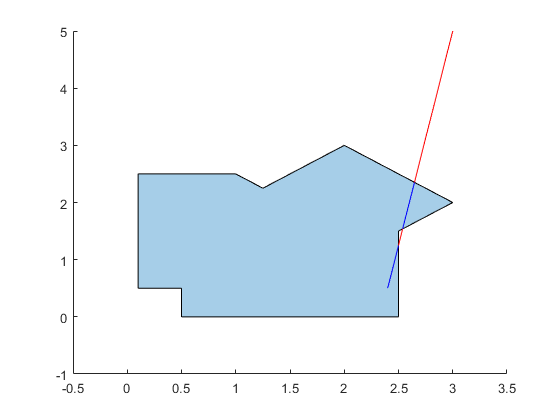

[in,out] = intersect(poly_map,lineseg);
hold on
plot(in(:,1),in(:,2),'b',out(:,1),out(:,2),'r')

intersect_point = in(2,:)

intersect_point =     2.5000    1.2500


size(in,1)

ans = 5

if size(in)>=2
    disp('have intersection')
end

have intersection
